# Clasificador de clima

Ahora que tenemos las imágenes cortadas, entonces podemos pocreder a usarlas. Sin embargo, antes de eso debemos de separar las imágenes en 3 conjuntos: entrenamiento, validación y prueba. Sabemos lo siguiente gracias a los nombre de las imágenes:

- Tenemos 300 imágenes con Cloudy

- Tenemos 215 imágenes con Rain

- Tenemos 253 imágenes con Shine

- Tenemos 357 imágenes con Sunrise

Usaremos las primeras **190 imágenes de cada categoría** para conformar el dataset de entrenamiento, mientras que para el conjunto de validación usaremos **15 de cada categoría** y **el resto** será de prueba. Se renombraron las imágenes y se pusieron en carpetas con un nombre respectivo al del dataset al que pertenece. Con lo que para prueba nos quedan:

- 95 imágenes para Cloudy

- 10 imágenes para Rain

- 48 imágenes para Shine

- 152 imágenes para Sunrise

## Entrenamiento

En esta sección ponemos la conifguración inicial, como los hiperparámetros necesarios para la red neuronal, entre ellos las funciones que vamos a usar y la tasa de aprendizaje (alfa). Sabemos que las imágenes tienen un tamaño de 140 x 94, además de que tiene tres matrices para los colores RGB, por lo que comenzamos a definir las entradas. La entrada p, tendrá como tamaño 140 x 94 x 3 = 39480 x 1. 

alfa = 0.105;
capas = {@logsig, @logsig}; % Incluye la capa de salida
neuronas = [2, 1]; % Debe ser del tamaño de capas y la última capa debe tener 2
dsig = @(n) (1 - logsig(n))*logsig(n)';
derivadas = { dsig, dsig }; % Del tamaño de capas

assert(length(neuronas) == length(capas));
assert(length(derivadas) == length(capas));

num_capas = length(capas);
categorias = ["cloudy", "sunrise", "shine", "rain"];

% Asignamos los pesos de forma aleatoria según las neurononas y la entrada
entrada = 140 * 94 * 3; % base * altura * matrices RGB
pesos = cell(1, num_capas);
bias = cell(1, num_capas);

for i = 1:num_capas
    if i == 1
        pesos{i} = randn(neuronas(i), entrada);
    else
        pesos{i} = randn(neuronas(i), neuronas(i-1));
    end
    
    bias{i} = randn(neuronas(i), 1);
end

Aquí vamos a hacer el entrenamiento, y poder seleccionar algunos hiperparámetros para controlar cómo se entrena. Además, definimos cosas útiles como las etiquetas que tiene las imágenes de la siguiente forma:

- Cloudy: [0, 0]

- Rain: [0, 1]

- Shine: [1, 0]

- Sunrise: [1, 1]

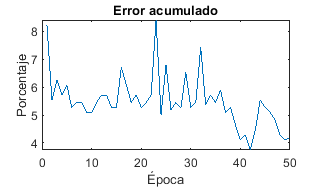

num_epocas = 50;
errores = zeros(1, num_epocas); % Para hacer un plot al final
etiquetas = {0, 1, [0; 0], [0; 1], [1; 0], [1; 1]}; % Etiquetas de las imágenes
salidas = cell(1, num_capas + 1);
sensitividades = cell(1, num_capas);


num_imagenes = 190;
error_acumulado = 100;
error = 0;
epoca = 0;

while error_acumulado > 0.5 && epoca < num_epocas % Este loop marca las épocas
    epoca = epoca + 1;
    error_acumulado = 0;
    
    for j = 1:190 % Recorre las imágenes
        for i = 1:2 % Recorre las categorías
            % Seleccionamos la imagen y la hacemos vector
            name = strcat("./training/", categorias(i), num2str(j), ".jpg");
            p = double(reshape(imread(name), [entrada, 1]));
            salida = p;
            salidas{1} = salida;
            
            % Propagación hacia adelante
            for k = 1:num_capas
                    salida = capas{k}(pesos{k} * salida + bias{k});
                    salidas{k+1} = salida;
            end
            
            % Calculamos el error
            salida(salida>0.5) = 1;
            salida(salida<=0.5) = 0;
            salidas{k+1} = salida;
            
            error = etiquetas{i} - salida;
            error_acumulado = error_acumulado + error' * error;
            
            if ~isequal(error, zeros(neuronas(end), 1))
                for k = num_capas:-1:1
                    if k == num_capas
                        sensitividades{k} = -2 * eye(neuronas(k)) * derivadas{k}(salidas{k+1}) * error;
                    else
                        sensitividades{k} = eye(neuronas(k)) * derivadas{k}(salidas{k+1})...
                                        * pesos{k+1}' * sensitividades{k+1};
                    end
                end
                
                for k = num_capas:-1:1
                    pesos{k} = pesos{k} - alfa * sensitividades{k} * salidas{k}';
                    bias{k} = bias{k} - alfa * sensitividades{k};
                end
            end
        end
    end
    
    % Calculamos el error acumulado
    error_acumulado = 100 * error_acumulado / (length(salida) * 140 * 4);
    errores(epoca) = error_acumulado;
end

plot(1:epoca, errores);
title("Error acumulado");
ylabel("Porcentaje");
xlabel("Época");

## Validación

error_acumulado = 0;
total = 15 * 4;
fallidos = 0;

for j = 1:15 % Recorre las imágenes
    for i = 1:2 % Recorre las categorías
        % Seleccionamos la imagen y la hacemos vector
        name = strcat("./validation/", categorias(i), num2str(j), ".jpg");
        p = double(reshape(imread(name), [entrada, 1]));
        salida = p;
        
        % Propagación hacia adelante
        for k = 1:num_capas
                salida = capas{k}(pesos{k} * salida + bias{k});
        end
        
        % Calculamos el error
        salida(salida>0.5) = 1;
        salida(salida<=0.5) = 0;
        salidas{k+1} = salida;
        
        error = etiquetas{i} - salida;
        error_acumulado = error_acumulado + error' * error;
        
        if ~isequal(error, zeros(neuronas(end), 1))
            fallidos = fallidos + 1;
        end
    end
end

error_acumulado = 100 * error_acumulado / (length(salida) * total);

fprintf("Los hiperparámetros son:");

Los hiperparámetros son:

fprintf("\tTasa de aprendizaje alfa: %f", alfa);

	Tasa de aprendizaje alfa: 0.105000

fprintf("\tNúmero de capas: %d", num_capas);

	Número de capas: 2

fprintf("\tNúmero de neuronas: " + num2str(neuronas));

	Número de neuronas: 2  1


fprintf("\nLos resultados del modelo son:");


Los resultados del modelo son:

fprintf("\tError acumulado: %f %%", error_acumulado);

	Error acumulado: 5.000000%

fprintf("\tCasos totales: %d", total);

	Casos totales: 60

fprintf("\tCasos fallidos: %d", fallidos);

	Casos fallidos: 3

## Prueba

El modelo dice que es: sunrise
./testing/sunrise38.jpg


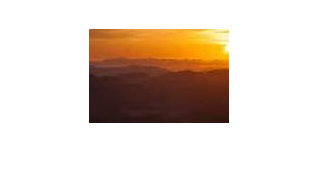

% Seleccionamos una imagen al azar
maximos = [95, 152, 48, 10];
categoria = randi(2, [1, 1]);
j = randi(maximos(categoria), [1, 1]);
name = strcat("./testing/", categorias(categoria), num2str(j), ".jpg");
[p, m] = imread(name);
salida = double(reshape(p, [entrada, 1]));

% Propagación hacia adelante
for k = 1:num_capas
    salida = capas{k}(pesos{k} * salida + bias{k});
end
salida(salida > 0.5) = 1;
salida(salida <= 0.5) = 0;

% Revisamos la salida
for i = 1:4
    if isequal(etiquetas{i}, salida)
        res = categorias(i);
        break;
    end
end

fprintf("El modelo dice que es: %s\n", res); disp(name); imshow(p, m);